DENTIFICACIÓN DEL SISTEMA: RESPUESTA AL ESCALÓN Y PRBS

- Procesa datos de simulación (escalón)

- Procesa datos medidos del escalón real

- Procesa datos medidos del ensayo PRBS

- Filtra, normaliza y genera iddata para System Identification

## DATOS DE SIMULACIÓN DEL ESCALÓN


datos_sim = readmatrix('datos_escalon_simulacion.DAT');

t_sim = datos_sim(:,1) - 3.006216984;
y_sim = datos_sim(:,2) - min(datos_sim(:,2));   % salida normalizada
u_sim = datos_sim(:,3) * (3/5);                 % reescala la entrada

Ts_sim = mean(diff(t_sim));

% --- Filtrado temporal por remuestreo manual ---
t_inicio = 0;
t_fin    = 6;
dt       = 0.001;

Npts = floor((t_fin - t_inicio)/dt);
i = 1;

Tt_sim = zeros(1, Npts);
u_sim_filt = zeros(1, Npts);
y_sim_filt = zeros(1, Npts);

for k = 1:Npts
    while (i < length(t_sim)) && (t_sim(i) < t_inicio + k*dt)
        i = i + 1;
    end
    Tt_sim(k) = (k-1)*dt;
    u_sim_filt(k) = u_sim(i);
    y_sim_filt(k) = y_sim(i);
end

u_sim_filt(1) = 0;

% Defino el objeto  para el system identification
data_sim_escalon = iddata(y_sim_filt', u_sim_filt', dt);



## DATOS MEDIDOS DEL ESCALÓN REAL


datos_escalon = readtable('datos_escalon_medido.CSV');

t_escalon = datos_escalon.Var4(4:end) + 3; % corrige offset
T_escalon = mean(diff(t_escalon));

y_escalon = datos_escalon.Var5(4:end);
y_escalon = y_escalon - mean(y_escalon(1:6000));   % elimina offset

% --- Filtro pasabajos ---
fs = 1/T_escalon;
fc = 50;
[b_med, a_med] = butter(4, fc/(fs/2));

y_med_filt = filter(b_med, a_med, y_escalon);

% --- Procesamiento de la entrada ---
u_escalon = datos_escalon.Var6(4:end);
u_escalon(u_escalon < 4) = 0;
u_escalon(u_escalon >= 4) = 3;

data_med_escalon = iddata(y_med_filt, u_escalon, T_escalon);

% Transferencia ideal ejemplo
s = tf('s');
G_ideal = 1/(s*0.1 + 1)^6;



## DATOS MEDIDOS PRBS REAL


datos_prbs = readtable('datos_prbs_medido.CSV');

T_prbs = 1/200;

% --- Salida ---
y_prbs = datos_prbs.Var2;
y_prbs = (y_prbs - 1000) / 3000;

% recorta negativos
y_prbs(y_prbs < 0) = 0;

% --- Entrada ---
u_prbs = datos_prbs.Var1;
u_prbs(u_prbs < 2500) = 0;
u_prbs(u_prbs >= 2500) = 1;

data_med_prbs = iddata(y_prbs, u_prbs, T_prbs);


## APROXIMACIÓN FOPDT 

Basado en el modelo obtenido en el ensayo de PRBS y del escalón, se obtuvo:


$$\begin{array}{l}
G_{\textrm{FOPDT}} =\frac{K_p e^{-\textrm{Ls}} }{1+\textrm{Ts}}=\frac{\left(0\ldotp 98257\right)e^{-\left(0\ldotp 34639\right)s} }{1+\left(0\ldotp 50484\right)s}\\
\\
T=0\ldotp 50484\\
L=0\ldotp 34639\\
K_{p\;} =0\ldotp 98257
\end{array}$$


% Defino el modelo FOPDT y los parámetros del PID
s = tf('s');

T =  0.50484;
L  = 0.34639;
K_p = 0.98257;

G_sin_retardo = (K_p)/(1+s*T);
G_fopdt = G_sin_retardo; 
G_fopdt.InputDelay = L; 
G_aprox = G_sin_retardo*(1-(s*L/2))/(1+(s*L/2));  %  Aproximado por Padé

G_aprox =
 
      -0.296 s + 3.946
  ------------------------
  0.2269 s^2 + 3.325 s + 4
 
Continuous-time transfer function.



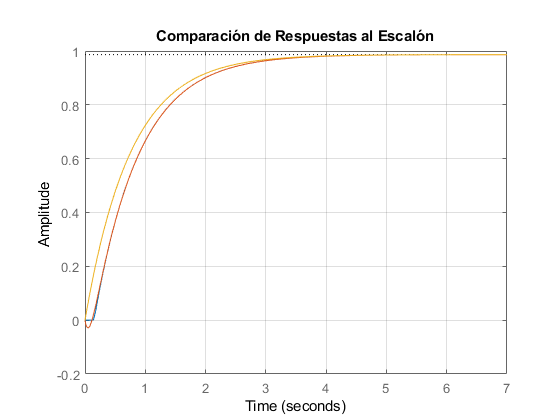


% grafico

figure;
h = stepplot(G_fopdt, G_aprox, G_sin_retardo);
grid on;
title("Comparación de Respuestas al Escalón");

## DISEÑO DEL PID (asignacion de polos)

Basado el el modelo aproximado de primer orden, se diseña el PID


$$G_{\mathrm{aprox}} \;\;=\;\frac{\left(0\ldotp 98662\right)\left(1-\frac{\left(\mathrm{s0}\ldotp 15\right)}{2}\right)}{\left(1+\left(0\ldotp 75618\right)s\right)\left(1+\frac{s\left(0\ldotp 15\right)}{2}\right)}$$



$$PID_{SP}(s) = 
\frac{k_c (1 + T_I s)(1 + T_D s)}
{T_I s (1 + \alpha T_D s)},$$


% Defino parametros del modelo
s = tf('s');

T =  0.50484;
L  = 0.34639;
K_p = 0.98257;

G_sin_retardo = (K_p)/(1+s*T);
G_fopdt = G_sin_retardo; 
G_fopdt.InputDelay = L; 

% Defino parametros del PID

T_D = 0.5*L;
T_I = T;
alfa = 0.6;
T_0 = (sqrt(alfa*alfa + alfa) + alfa)*L/2

T_0 = 0.2736

k_c  = 2*T/(K_p*(L  + 4*T_0));

% Calculo transferencias del PID

G_aprox = G_sin_retardo * (1 - (L/2)*s) / (1 + (L/2)*s);
PID = (k_c*(1+T_I*s)*(1+T_D*s))/(T_I*s*(1+alfa*T_D*s))

PID =
 
                                
  0.06236 s^2 + 0.4836 s        
                                
                        + 0.7132
                                
  ------------------------------
                            
      0.05246 s^2 + 0.5048 s
                            
 
Continuous-time transfer function.



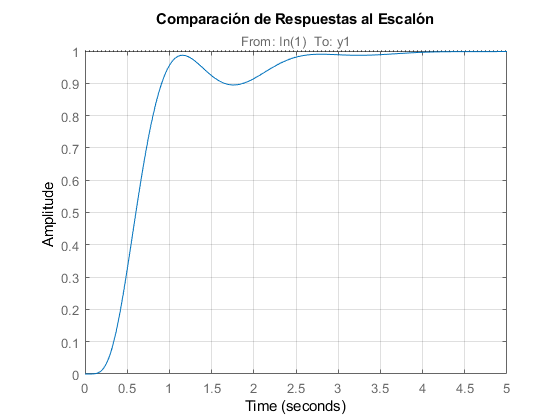


Taprox = feedback(G_aprox*PID, 1);
Treal = feedback(G_fopdt*PID, 1);
Tposta = feedback(G_posta*PID, 1);

Tideal = feedback(G_ideal*PID,1);
% grafico

figure;
h = stepplot(Tposta);
grid on;
title("Comparación de Respuestas al Escalón");

## Discretizacion de la planta

% Defino parametros del modelo
s = tf('s');

T =  0.50484;
L  = 0.34639;
K_p = 0.98257;

% Defino parametros del PID

T_D = 0.5*L;
T_I = T;
alfa = 0.6;
T_0 = (sqrt(alfa*alfa + alfa) + alfa)*L/2;
k_c  = 2*T/(K_p*(L  + 4*T_0));

PID = (k_c*(1+T_I*s)*(1+T_D*s))/(T_I*s*(1+alfa*T_D*s));



s = tf('s');

T  = 0.50484;
L  = 0.34639;
Kp = 0.98257;

TD   = 0.5*L;
TI   = T;
alfa = 0.6;

T0 = (sqrt(alfa^2 + alfa) + alfa)*L/2;
kc = 2*T / (Kp*(L + 4*T0));

G = (kc*(1+TI*s)*(1+TD*s)) / (TI*s*(1+alfa*TD*s))


G =
 
  0.06236 s^2 + 0.4836 s + 0.7132
  -------------------------------
      0.05246 s^2 + 0.5048 s
 
Continuous-time transfer function.
Model Properties



Ts = 0.001;
Gd = c2d(G, Ts, 'tustin');

[num, den] = tfdata(Gd, 'v')

num =     1.1875   -2.3659    1.1784


den =     1.0000   -1.9904    0.9904
